clear 
clc
step = @(t) heaviside(t); 
e = 2.718;
% risposta al gradino del sistema sottosmorzato con -1<delta<0
delta = -0.3;
fi = acos(delta)

fi = 1.8755

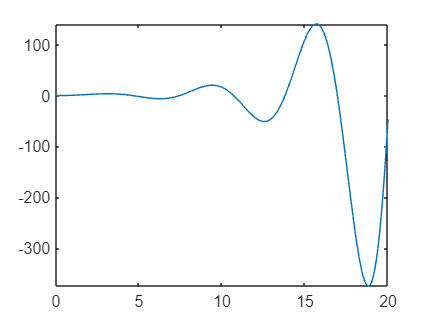

wn = 1.05;
wd = wn.*sin(fi);
y =@(t) 1-e.^(-delta.*wn*t).*sin(wd.*t+fi)/sqrt(1-delta.^2);
fplot(y,[0,20])

% risposta al gradino del sistema sottosmorzato con delta = 0
fi = pi/2

fi = 1.5708

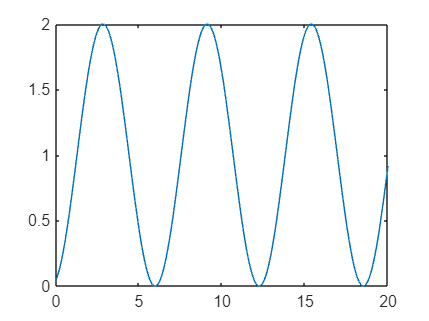

delta = 0;
wd = wn.*sin(fi);
y =@(t) 1-e.^(-delta.*wn*t).*sin(wd.*t+fi)/sqrt(1-delta.^2);
fplot(y,[0,20])

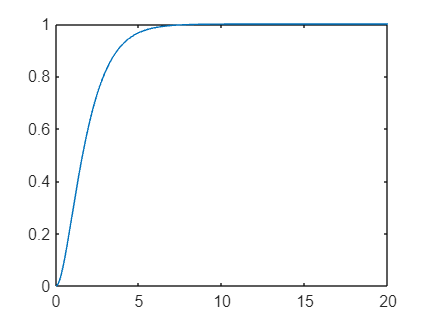

% risposta al gradino con smorzamento critico delta = 1
delta = 1;
y =@(t) 1-wn.*t.*e.^(-wn.*t)-e.^(-wn.*t);
fplot(y, [0 20]);

% risposta al gradino con smorzamento critico delta = -1
delta = -1;
y = @(t) 1 + wn.*t.*e.^(wn.*t)-e.^(wn.*t)

y = function_handle with value:
    @(t)1+wn.*t.*e.^(wn.*t)-e.^(wn.*t)


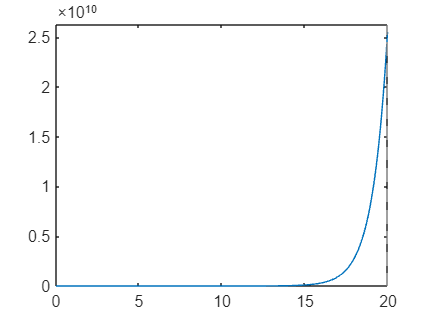

fplot(y, [0 20]);

% risposta al gradino del sistema sovrasmorzato delta > 1
delta = 1.732;
p1 = -delta.*wn - wn.*sqrt(delta.^2-1);
p2 = -delta.*wn + wn.*sqrt(delta.^2-1);
y=@(t) 1+ (wn.*(-e.^(p1.*t)/p1 + e.^(p2.*t)/p2))/(2.*sqrt(delta.^2-1))

y = function_handle with value:
    @(t)1+(wn.*(-e.^(p1.*t)/p1+e.^(p2.*t)/p2))/(2.*sqrt(delta.^2-1))


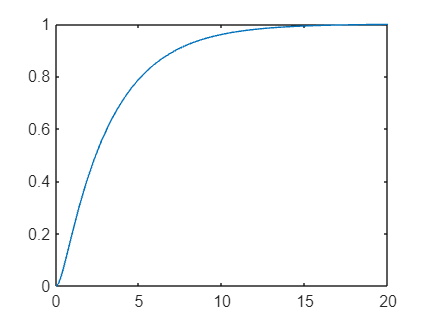

fplot(y, [0 20]);

%risposta al gradino del sistema sovrasmorzato delta < -1
delta = - 1.732;
p1 = -delta.*wn - wn.*sqrt(delta.^2-1);
p2 = -delta.*wn + wn.*sqrt(delta.^2-1);
y=@(t) 1+ (wn.*(-e.^(p1.*t)/p1 + e.^(p2.*t)/p2))/(2.*sqrt(delta.^2-1))

y = function_handle with value:
    @(t)1+(wn.*(-e.^(p1.*t)/p1+e.^(p2.*t)/p2))/(2.*sqrt(delta.^2-1))


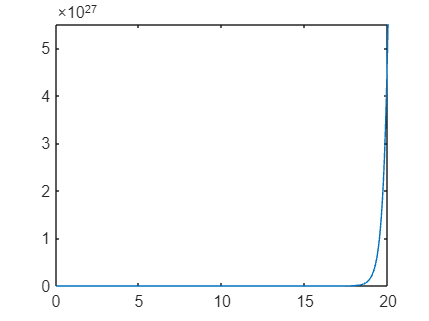

fplot(y, [0 20]);